# LAB 01.04.2025

## Pendulum - homework

% _/_/_/_/_/_/_
%       |\
%  |    | \
%  | g  |  \ l 
%  V    | x \   (x=theta)
%       |    \
%       |     \
%       |      m
% 
% note: no energy dissipation
% note: no external force

clear
syms theta(t) m l g L V T

% Kinetic energy
T = 0.5 * m * l^2 * diff(theta, 1, t)^2

$$T(t) = \frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

% Potential energy
V = m * g * l * cos(theta)

$$V(t) = g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

% Lagrange equation
L = T - V

$$L(t) = \frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

% Differentiations
diff_t_q_prim = diff(diff(L, 1, diff(theta)), 1, t)

$$diff\_t\_q\_prim(t) = l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

diff_q = diff(L, 1, theta)

$$diff\_q(t) = g\,l\,m\,\sin\left(\theta \left(t\right)\right)$$

% Final differential equation (u = d/dt(dL/dq') - dL/dq + dP/dq')
eqn = 0 == diff_t_q_prim - diff_q

$$eqn(t) = 0=l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-g\,l\,m\,\sin\left(\theta \left(t\right)\right)$$

eqn = isolate(eqn, diff(theta, 2))

$$eqn = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{g\,\sin\left(\theta \left(t\right)\right)}{l}$$

## Series RLC circuit

clear
syms R L C u(t) q(t)

% Kinetic energy
T = 0.5 * L * diff(q, 1, t)^2

$$T(t) = \frac{L\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}}{2}$$

% Potential energy
V = 0.5 * q^2 / C

$$V(t) = \frac{{q\left(t\right)}^{2}}{2\,C}$$

% Energy dissipation
P = 0.5 * R * diff(q, 1, t)^2

$$P(t) = \frac{R\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}}{2}$$

% Lagrange equation
L = T - V

$$L(t) = \frac{L\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}}{2}-\frac{{q\left(t\right)}^{2}}{2\,C}$$

% Differentiations
diff_t_q_prim = diff(diff(L, 1, diff(q)), 1, t)

$$diff\_t\_q\_prim(t) = L\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)$$

diff_q = diff(L, 1, q)

$$diff\_q(t) = -\frac{q\left(t\right)}{C}$$

diff_q_prim = diff(P, 1, diff(q))

$$diff\_q\_prim(t) = R\,\frac{\partial }{\partial t}q\left(t\right)$$

% Final differential equation (u = d/dt(dL/dq') - dL/dq + dP/dq')
eqn = u == diff_t_q_prim - diff_q + diff_q_prim

$$eqn(t) = u\left(t\right)=R\,\frac{\partial }{\partial t}q\left(t\right)+L\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\frac{q\left(t\right)}{C}$$

eqn = isolate(eqn, diff(q, 2))

$$eqn = \frac{\partial^{2}}{\partial t^{2}}q\left(t\right)=-\frac{R\,\frac{\partial }{\partial t}q\left(t\right)-u\left(t\right)+\frac{q\left(t\right)}{C}}{L}$$

## Two degrees of freedom robotic arm

clear
syms r(t) theta(t) m g f(t) gamma(t)
syms b1 b2
q = [theta; r]

$$q(t) = \left(\begin{array}{c} \theta \left(t\right)\\ r\left(t\right) \end{array}\right)$$

Q = [gamma; f]

$$Q(t) = \left(\begin{array}{c} \gamma \left(t\right)\\ f\left(t\right) \end{array}\right)$$

% Moment of inertia
J = m * r^2

$$J(t) = m\,{r\left(t\right)}^{2}$$

% Kinetic energy
T = 0.5 * J * diff(theta, 1)^2 + 0.5 * m * diff(r, 1)^2

$$T(t) = \frac{m\,{r\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}r\left(t\right)\right)}^{2}}{2}$$

% Potential energy
V = m * g * r * sin(theta)

$$V(t) = g\,m\,\sin\left(\theta \left(t\right)\right)\,r\left(t\right)$$

% Energy dissipation
P = 0.5 * b1 * diff(theta, 1, t)^2 + 0.5 * b2 * diff(r, 1, t)^2

$$P(t) = \frac{b_{2}\,{\left(\frac{\partial }{\partial t}r\left(t\right)\right)}^{2}}{2}+\frac{b_{1}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

% Lagrange equation
L = T - V

$$L(t) = \frac{m\,{r\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}r\left(t\right)\right)}^{2}}{2}-g\,m\,\sin\left(\theta \left(t\right)\right)\,r\left(t\right)$$

% Differentiations
diff_t_q_prim = diff(jacobian(L, diff(q, t)), t).'

$$diff\_t\_q\_prim(t) = \left(\begin{array}{c} m\,{r\left(t\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,m\,\frac{\partial }{\partial t}\theta \left(t\right)\,r\left(t\right)\,\frac{\partial }{\partial t}r\left(t\right)\\ m\,\frac{\partial^{2}}{\partial t^{2}}r\left(t\right) \end{array}\right)$$

diff_q = jacobian(L, q).'

$$diff\_q(t) = \left(\begin{array}{c} -g\,m\,\cos\left(\theta \left(t\right)\right)\,r\left(t\right)\\ m\,r\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-g\,m\,\sin\left(\theta \left(t\right)\right) \end{array}\right)$$

diff_q_prim = jacobian(P, diff(q, t)).'

$$diff\_q\_prim(t) = \left(\begin{array}{c} b_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ b_{2}\,\frac{\partial }{\partial t}r\left(t\right) \end{array}\right)$$

% Final differential equation (u = d/dt(dL/dq') - dL/dq + dP/dq')
eqn = Q == diff_t_q_prim - diff_q + diff_q_prim

$$eqn(t) = \left(\begin{array}{c} \gamma \left(t\right)=m\,{r\left(t\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2\,m\,\frac{\partial }{\partial t}\theta \left(t\right)\,r\left(t\right)\,\frac{\partial }{\partial t}r\left(t\right)+b_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+g\,m\,\cos\left(\theta \left(t\right)\right)\,r\left(t\right)\\ f\left(t\right)=m\,\frac{\partial^{2}}{\partial t^{2}}r\left(t\right)-m\,r\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+b_{2}\,\frac{\partial }{\partial t}r\left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right) \end{array}\right)$$

## Transition to the state space

syms x1(t) x2(t) x3(t) x4(t)
x = [x1 == theta; x2 == diff(theta); x3 == r; x4 == diff(r)] % [theta, theta_dot, r, r_dot]

$$x(t) = \left(\begin{array}{c} x_{1}\left(t\right)=\theta \left(t\right)\\ x_{2}\left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right)\\ x_{3}\left(t\right)=r\left(t\right)\\ x_{4}\left(t\right)=\frac{\partial }{\partial t}r\left(t\right) \end{array}\right)$$

subs_eqs = subs(eqn, [theta, diff(theta), r, diff(r)], [x1, x2, x3, x4])

$$subs\_eqs(t) = \left(\begin{array}{c} \gamma \left(t\right)=b_{1}\,\frac{\partial }{\partial t}x_{1}\left(t\right)+m\,{x_{3}\left(t\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)+2\,m\,x_{3}\left(t\right)\,\frac{\partial }{\partial t}x_{3}\left(t\right)\,\frac{\partial }{\partial t}x_{1}\left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)\\ f\left(t\right)=m\,\frac{\partial^{2}}{\partial t^{2}}x_{3}\left(t\right)-m\,x_{3}\left(t\right)\,{\left(\frac{\partial }{\partial t}x_{1}\left(t\right)\right)}^{2}+b_{2}\,\frac{\partial }{\partial t}x_{3}\left(t\right)+g\,m\,\sin\left(x_{1}\left(t\right)\right) \end{array}\right)$$

subs_eqs = subs(subs_eqs, [diff(x1,2), diff(x3,2)], [diff(x2), diff(x4)])

$$subs\_eqs(t) = \left(\begin{array}{c} \gamma \left(t\right)=b_{1}\,\frac{\partial }{\partial t}x_{1}\left(t\right)+m\,{x_{3}\left(t\right)}^{2}\,\frac{\partial }{\partial t}x_{2}\left(t\right)+2\,m\,x_{3}\left(t\right)\,\frac{\partial }{\partial t}x_{3}\left(t\right)\,\frac{\partial }{\partial t}x_{1}\left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)\\ f\left(t\right)=b_{2}\,\frac{\partial }{\partial t}x_{3}\left(t\right)+m\,\frac{\partial }{\partial t}x_{4}\left(t\right)+g\,m\,\sin\left(x_{1}\left(t\right)\right)-m\,x_{3}\left(t\right)\,{\left(\frac{\partial }{\partial t}x_{1}\left(t\right)\right)}^{2} \end{array}\right)$$

subs_eqs = subs(subs_eqs, [diff(x1), diff(x3)], [x2, x4])

$$subs\_eqs(t) = \left(\begin{array}{c} \gamma \left(t\right)=b_{1}\,x_{2}\left(t\right)+m\,{x_{3}\left(t\right)}^{2}\,\frac{\partial }{\partial t}x_{2}\left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)\\ f\left(t\right)=m\,\frac{\partial }{\partial t}x_{4}\left(t\right)-m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+b_{2}\,x_{4}\left(t\right)+g\,m\,\sin\left(x_{1}\left(t\right)\right) \end{array}\right)$$

[1,0]*subs_eqs

$$ans(t) = \gamma \left(t\right)=b_{1}\,x_{2}\left(t\right)+m\,{x_{3}\left(t\right)}^{2}\,\frac{\partial }{\partial t}x_{2}\left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)$$

[0,1]*subs_eqs

$$ans(t) = f\left(t\right)=m\,\frac{\partial }{\partial t}x_{4}\left(t\right)-m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+b_{2}\,x_{4}\left(t\right)+g\,m\,\sin\left(x_{1}\left(t\right)\right)$$

ss_eqs = [diff(x1) == x2; isolate([1,0]*subs_eqs, diff(x2, 1, t));
          diff(x3) == x4; isolate([0,1]*subs_eqs, diff(x4, 1, t))]

$$ss\_eqs(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=-\frac{b_{1}\,x_{2}\left(t\right)-\gamma \left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)}{m\,{x_{3}\left(t\right)}^{2}}\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+f\left(t\right)-b_{2}\,x_{4}\left(t\right)-g\,m\,\sin\left(x_{1}\left(t\right)\right)}{m} \end{array}\right)$$

## Finding the equilibrium points

subs_eqs = subs(ss_eqs, [diff(x1), diff(x2), diff(x3), diff(x4)], [0, 0, 0, 0])

$$subs\_eqs(t) = \left(\begin{array}{c} 0=x_{2}\left(t\right)\\ 0=-\frac{b_{1}\,x_{2}\left(t\right)-\gamma \left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)}{m\,{x_{3}\left(t\right)}^{2}}\\ 0=x_{4}\left(t\right)\\ 0=\frac{m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+f\left(t\right)-b_{2}\,x_{4}\left(t\right)-g\,m\,\sin\left(x_{1}\left(t\right)\right)}{m} \end{array}\right)$$

subs_eqs = subs(subs_eqs, [x2(t) x4(t)], [0 0])

$$subs\_eqs(t) = \left(\begin{array}{c} 0=0\\ 0=\frac{\gamma \left(t\right)-g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)}{m\,{x_{3}\left(t\right)}^{2}}\\ 0=0\\ 0=\frac{f\left(t\right)-g\,m\,\sin\left(x_{1}\left(t\right)\right)}{m} \end{array}\right)$$

subs_eqs = [isolate([0 1 0 0]*subs_eqs, gamma);
            isolate([0 0 0 1]*subs_eqs, f)]

$$subs\_eqs = \left(\begin{array}{c} \gamma \left(t\right)=g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)\\ f\left(t\right)=g\,m\,\sin\left(x_{1}\left(t\right)\right) \end{array}\right)$$

Therefore, when arm is horizontally (theta = x1 = 0) the f force needed is also equal to zero because (sin(0)*g*m = 0) 

And torque is strictly dependant on r = x3, torque is zero when robot is in upright position, theta = pi/2+2kpi but this is not the stable equilibrium, also torque is zero when r = x3 = 0

## Plot of force and torque

% define the range of r and theta (x3 and x1) in ranges [0.1m 1.1m] and [0 pi]
assumeAlso(r(t), 'real'); assumeAlso(r(t)>=0.1); assumeAlso(r(t)<=1.1); 
assumeAlso(theta(t), 'real'); assumeAlso(theta(t)>=0); assumeAlso(theta(t)<=pi); 
assumptions()

$$ans = \left(\begin{array}{cccccc} \frac{1}{10}\leq r\left(t\right) & r\left(t\right)\leq \frac{11}{10} & 0\leq \theta \left(t\right) & \theta \left(t\right)\leq \pi & r\left(t\right)\in \mathbb{R} & \theta \left(t\right)\in \mathbb{R} \end{array}\right)$$

% Substitute the mass and the acceleration
final_eqn = subs(subs_eqs, [m, g], [1, 9.80665])

$$final\_eqn = \left(\begin{array}{c} \gamma \left(t\right)=\frac{5520653160719109\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)}{562949953421312}\\ f\left(t\right)=\frac{5520653160719109\,\sin\left(x_{1}\left(t\right)\right)}{562949953421312} \end{array}\right)$$

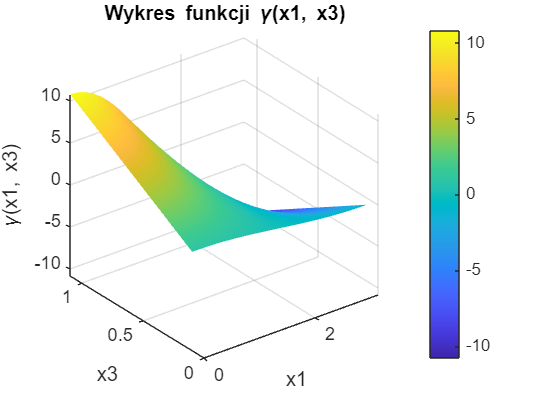


%% Zakresy zmiennych
x1_var = linspace(0, pi, 100);   % x1 od 0 do pi
x3_var = linspace(0.1, 1.1, 100); % x3 od 0.1 do 1.1

% Tworzenie siatki wartości
[X1, X3] = meshgrid(x1_var, x3_var);

% Obliczenie funkcji
gamma = (5520653160719109 * cos(X1) .* X3) / 562949953421312;

% Rysowanie wykresu 3D
figure;
surf(X1, X3, gamma);
xlabel('x1');
ylabel('x3');
zlabel('\gamma(x1, x3)');
title('Wykres funkcji \gamma(x1, x3)');
colorbar;
shading interp;

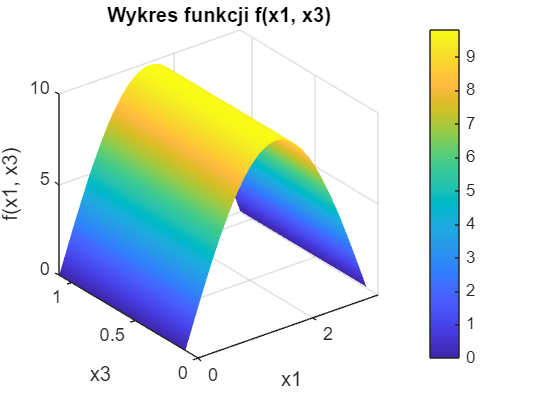


% Obliczenie funkcji
f = (5520653160719109 * sin(X1)) / 562949953421312;

% Rysowanie wykresu 3D
figure;
surf(X1, X3, f);
xlabel('x1');
ylabel('x3');
zlabel('f(x1, x3)');
title('Wykres funkcji f(x1, x3)');
colorbar;
shading interp;

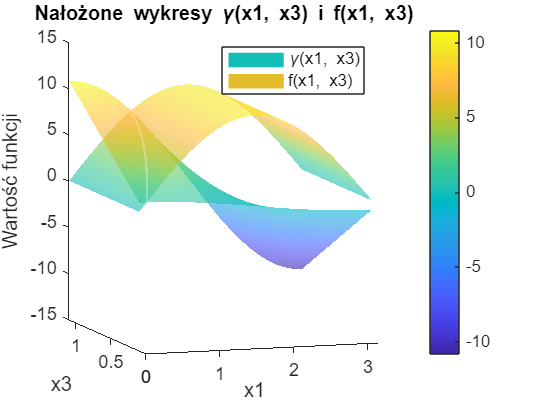


% Rysowanie wykresów na jednym wykresie
figure;
hold on;
surf(X1, X3, gamma, 'FaceAlpha', 0.6); % Przezroczystość 60%
surf(X1, X3, f, 'FaceAlpha', 0.6);     % Przezroczystość 60%
hold off;

xlabel('x1');
ylabel('x3');
zlabel('Wartość funkcji');
title('Nałożone wykresy \gamma(x1, x3) i f(x1, x3)');
colorbar;
shading interp;
legend({'\gamma(x1, x3)', 'f(x1,  x3)'});
view([-18.3 7.4])

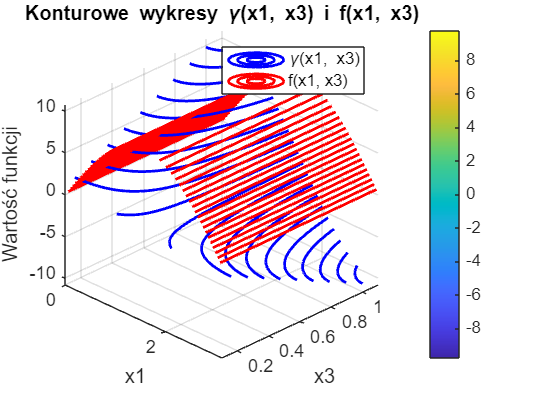


% Rysowanie wykresów konturowych na jednym wykresie
figure;
hold on;
contour3(X1, X3, gamma, 20, 'b', 'LineWidth', 1.5); % Kontury gamma (niebieskie)
contour3(X1, X3, f, 20, 'r', 'LineWidth', 1.5); % Kontury f (czerwone)
hold off;

xlabel('x1');
ylabel('x3');
zlabel('Wartość funkcji');
title('Konturowe wykresy \gamma(x1, x3) i f(x1, x3)');
colorbar;
legend({'\gamma(x1, x3)', 'f(x1, x3)'});
view([45 30]); % Ustawienie kąta widoku
grid on;

You can observe the isolines where:

- for f (red lines) the isolnes are perpendicular and only in horizontal direction, bilinear to x3  axis -> that means the f (force) does not depends on the x3 value, it is the same whatever the x3 value is

- for gamma (blue lines) you can observe the curved isolines where torque remains cosntant. The torque depends only on the distance of the mass from the vertical axis going through the middle of the pivot point. Additionally on one side of that axis the torque is positive and on the other it is negative. (to the left and to the right) 

## clear workspace from unnecessary variables

clear ans diff_q_prim diff_q diff_t_q_prim
f0_gamma0_equations = subs_eqs

$$f0\_gamma0\_equations = \left(\begin{array}{c} \gamma \left(t\right)=g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)\\ f\left(t\right)=g\,m\,\sin\left(x_{1}\left(t\right)\right) \end{array}\right)$$

state_space_equations = ss_eqs

$$state\_space\_equations(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=-\frac{b_{1}\,x_{2}\left(t\right)-\gamma \left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)}{m\,{x_{3}\left(t\right)}^{2}}\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+f\left(t\right)-b_{2}\,x_{4}\left(t\right)-g\,m\,\sin\left(x_{1}\left(t\right)\right)}{m} \end{array}\right)$$

clear subs_eqs ss_eqs

% save("equations.mat", "state_space_equations", "f0_gamma0_equations")